    % Wavelength vector (in nanometers)
    lambda = [600, 650, 700, 750, 800, 850, 900, 950, 1000, ...
              1050, 1100, 1150, 1200, 1250, 1300, 1350, 1400, 1450, 1500, 1526];
    
    % Beta2 vector (in 10^-25 s^2/m)
    beta2 = [0.3855, 0.2264, 0.1132, 0, -0.1038, -0.1792, -0.2547, -0.3208, ...
             -0.3679, -0.3868, -0.3679, -0.3113, -0.1887, -0.3774, 0.2169, ...
             0.500, 0.8774, 1.3208, 1.8873, 2.1604];
    
    %NL-PM-750
    wavelength = 1064e-9

wavelength =      1.064000000000000e-06


    pitch = 1.5         %[um]

pitch =      1.500000000000000e+00


    airhole_d = 1.0     %[um]

airhole_d =      1


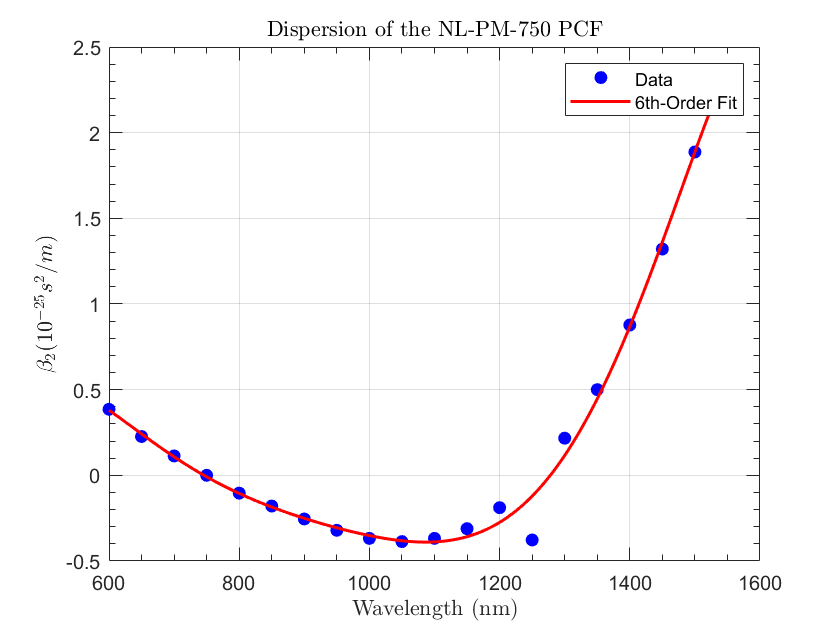

    
    % Center and scale the wavelength data
    lambda_mean = mean(lambda); % Compute mean
    lambda_scaled = (lambda - lambda_mean) / 100; % Center and scale by 100
    
    % Perform a 6th-order polynomial curve fit
    p = polyfit(lambda_scaled, beta2, 6);
    % Generate smooth points for the scaled wavelength
    lambda_fine = linspace(min(lambda), max(lambda), 500);
    lambda_fine_scaled = (lambda_fine - lambda_mean) / 100; % Scale fine grid
    
    % Evaluate the polynomial fit
    beta2_fit = polyval(p, lambda_fine_scaled);
    
    % Plot the original data
    figure;
    plot(lambda, beta2, 'bo', 'MarkerFaceColor', 'b', 'DisplayName', 'Data'); hold on;
    
    % Plot the 6th-order polynomial fit
    plot(lambda_fine, beta2_fit, 'r-', 'LineWidth', 1.5, 'DisplayName', '6th-Order Fit');
    
    % Enhance the plot appearance
    grid on;
    box on
    set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
        'TickLength', [0.02, 0.04], 'LineWidth', 0.5);
    xlabel('Wavelength (nm)', "Interpreter","latex");
    ylabel('$\beta_2 (10^{-25} s^2/m)$', "Interpreter","latex");
    title('Dispersion of the NL-PM-750 PCF', "Interpreter","latex");
    legend('show');

    
    % Wavelength to evaluate
    lambda_target = 1064;
    
    % Scale the target wavelength
    lambda_target_scaled = (lambda_target - lambda_mean) / 100;
    
    % Evaluate the polynomial at the scaled wavelength
    beta2_target = polyval(p, lambda_target_scaled);    
    
    % Compute derivatives of the polynomial for each beta_n
    beta3_poly = polyder(p);            % 1st derivative: beta3
    beta4_poly = polyder(beta3_poly);  % 2nd derivative: beta4
    beta5_poly = polyder(beta4_poly);  % 3rd derivative: beta5
    beta6_poly = polyder(beta5_poly);  % 4th derivative: beta6
    
    % Evaluate each beta_n at the scaled target wavelength
    beta3_target = polyval(beta3_poly, lambda_target_scaled); % beta3
    beta4_target = polyval(beta4_poly, lambda_target_scaled); % beta4
    beta5_target = polyval(beta5_poly, lambda_target_scaled); % beta5
    beta6_target = polyval(beta6_poly, lambda_target_scaled); % beta6
    
    % Display results
    % Display the result
    fprintf('The beta2 value at %f nm is %.6f (10^-25 s^2/m)\n', lambda_target, beta2_target);

The beta2 value at 1064.000000 nm is -0.386602 (10^-25 s^2/m)


    fprintf('The beta3 value at %f nm is %.6f (10^-40 s^3/m)\n', lambda_target, beta3_target);

The beta3 value at 1064.000000 nm is -0.026623 (10^-40 s^3/m)


    fprintf('The beta4 value at %f nm is %.6f (10^-55 s^4/m)\n', lambda_target, beta4_target);

The beta4 value at 1064.000000 nm is 0.107031 (10^-55 s^4/m)


    fprintf('The beta5 value at %f nm is %.6f (10^-70 s^5/m)\n', lambda_target, beta5_target);

The beta5 value at 1064.000000 nm is 0.099918 (10^-70 s^5/m)


    fprintf('The beta6 value at %f nm is %.6f (10^-85 s^6/m)\n', lambda_target, beta6_target);

The beta6 value at 1064.000000 nm is 0.064570 (10^-85 s^6/m)
